**The simulations for the global genetic perturbations.**

**For Figure 2.**

Initialization

%Basic paramters
load ../Parameter_determination/Basic_parameters.mat


%Modify the basic parameters
%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt]
mean_k0=para_opt(1)/8;
mean_am=para_opt(5);
mean_ax=para_opt(6);
mean_ay=para_opt(7);
mean_bx=para_opt(9);
mean_bm=para_opt(8);
mean_Kx=para_opt(2);
mean_Km=para_opt(4);
mean_Vn=2.8;
mean_Vc=37.2;
mean_Kv=5.8262;
mean_Ky=para_opt(3);
mean_Xt=para_opt(10);
mean_Yt=para_opt(11);

para0=para_opt;
para0(1)=para_opt(1)/8;



%%% Numerically solve the homeostatic values
load ../Solve_values/Solve_values.mat % Symbolic solutions
syms_solve=[Xn_pre,Xc_pre,Xp_pre,Yn_pre,Yp_pre];
syms k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv
para_sym=[k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv];
para_num=[para0,2.8,37.2,5.8262];
%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt]
temp1=double(subs(syms_solve,para_sym,para_num));% Xn Xc Xp Yn Yp
temp1=temp1(~any(temp1<0,2),:);
temp2=[2.8*para0(7)/para0(5),37.2*para0(9)/para0(8)];% mn mc
y_wt=[temp2,temp1]; %[mn mc Xn Xc Xp Yn Yp]

Xp=y_wt(5);
Yp=y_wt(7);

mn_wt=y_wt(1);
cmn_wt=mn_wt/mean_Vn;
mc_wt=y_wt(2);
cmc_wt=mc_wt/mean_Vc;

vpro_wt=mean_k0*...
    mean_Vn/(mean_Vn+mean_Kv)*...
    Xp/(Xp+mean_Kx*mean_Vn)*...
    mean_Vn*mean_Km/(mean_Vn*mean_Km+mn_wt)*...
    Yp/(Yp+mean_Ky*mean_Vn); % production rate

Xc=y_wt(4);
vdeg_wt=mean_bm*Xc*mc_wt/mean_Vc; % degradation rate



The simulations of perturbing kn

% Randomly sample paramters from lognormal distributions
nperm=500; %number of simulations

CV1=0.5;% The CVs of kn-related paramters

CV_k0=CV1;
sigma_norm=sqrt(log(1+CV_k0^2));
mean_norm=log(mean_k0)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
k0_ori=exp(norm);

CV_Kx=CV1;
sigma_norm=sqrt(log(1+CV_Kx^2));
mean_norm=log(mean_Kx)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
Kx_ori=exp(norm);

CV_Km=CV1;
sigma_norm=sqrt(log(1+CV_Km^2));
mean_norm=log(mean_Km)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
Km_ori=exp(norm);

CV_Vn=CV1;
sigma_norm=sqrt(log(1+CV_Vn^2));
mean_norm=log(mean_Vn)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
Vn_ori=exp(norm);

CV_Vc=CV1;
sigma_norm=sqrt(log(1+CV_Vc^2));
mean_norm=log(mean_Vc)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
Vc_ori=exp(norm);

CV_Kv=CV1;
sigma_norm=sqrt(log(1+CV_Kv^2));
mean_norm=log(mean_Kv)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
Kv_ori=exp(norm);

CV_Ky=CV1;
sigma_norm=sqrt(log(1+CV_Ky^2));
mean_norm=log(mean_Ky)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
Ky_ori=exp(norm);

CV_Yt=CV1;
sigma_norm=sqrt(log(1+CV_Yt^2));
mean_norm=log(mean_Yt)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
Yt_ori=exp(norm);

CV_Xt=CV1;
sigma_norm=sqrt(log(1+CV_Xt^2));
mean_norm=log(mean_Xt)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
Xt_ori=exp(norm);



CV2=0.1;% The CVs of other paramters

CV_am=CV2;
sigma_norm=sqrt(log(1+CV_am^2));
mean_norm=log(mean_am)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
am_ori=exp(norm);

CV_ax=CV2;
sigma_norm=sqrt(log(1+CV_ax^2));
mean_norm=log(mean_ax)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
ax_ori=exp(norm);

CV_ay=CV2;
sigma_norm=sqrt(log(1+CV_ay^2));
mean_norm=log(mean_ay)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
ay_ori=exp(norm);

CV_bx=CV2;
sigma_norm=sqrt(log(1+CV_bx^2));
mean_norm=log(mean_bx)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
bx_ori=exp(norm);

CV_bm=CV2;
sigma_norm=sqrt(log(1+CV_bm^2));
mean_norm=log(mean_bm)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
bm_ori=exp(norm);



%%% Simulations

mn_tot=zeros(1,nperm);
mc_tot=zeros(1,nperm);
Xn_tot=zeros(1,nperm);
Xc_tot=zeros(1,nperm);
Xp_tot=zeros(1,nperm);
Yn_tot=zeros(1,nperm);
Yp_tot=zeros(1,nperm);
vpro_tot=zeros(1,nperm);
vdeg_tot=zeros(1,nperm);

parfor j=1:nperm

    k0=k0_ori(j);
    am=am_ori(j);
    ax=ax_ori(j);
    ay=ay_ori(j);
    bx=bx_ori(j);
    bm=bm_ori(j);
    Kx=Kx_ori(j);
    Km=Km_ori(j);
    Xt=Xt_ori(j);
    Yt=Yt_ori(j);
    Vn=Vn_ori(j);
    Vc=Vc_ori(j);
    Kv=Kv_ori(j);
    Ky=Ky_ori(j);
    para0=[k0 Kx Ky Km am ax ay bm bx Xt Yt];
    para_num=[para0,Vn,Vc,Kv];
    %para:[k0 Kx Ky Km am ax ay bm bx Xt Yt]
    temp1=double(subs(syms_solve,para_sym,para_num));% Xn Xc Xp Yn Yp
    temp1=temp1(~any(temp1<0,2),:);
    temp2=[Vn*para0(7)/para0(5),Vc*para0(9)/para0(8)];% mn mc
    y_res=[temp2,temp1]; %[mn mc Xn Xc Xp Yn Yp]

    Xp=y_res(5);
    Yp=y_res(7);
    mn=y_res(1);
    vpro=(k0*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);

    Yn=y_res(6);
    vexp=am*Yn*mn/Vn;

    Xc=y_res(4);
    mc=y_res(2);
    vdeg=bm*Xc*mc/Vc;


    mn_tot(j)=random('Poisson',mn);%noise
    mc_tot(j)=random('Poisson',mc);%noise
    Xn_tot(j)=y_res(3);
    Xc_tot(j)=y_res(4);
    Xp_tot(j)=y_res(5);
    Yn_tot(j)=y_res(6);
    Yp_tot(j)=y_res(7);

    vpro_tot(j)=vpro+normrnd(0,(vpro*0.05)^2);%noise
    vdeg_tot(j)=vdeg+normrnd(0,(vdeg*0.05)^2);%noise
end


cmn_kn=mn_tot./Vn_ori';
cmc_kn=mc_tot./Vc_ori';
cm_kn=(mn_tot+mc_tot)./(Vn_ori'+Vc_ori');
vpro_kn=vpro_tot;


The simulations of perturbing am

% Randomly sample paramters from lognormal distributions
nperm=100; %number of simulations


CV_am=1;%The CV of am
sigma_norm=sqrt(log(1+CV_am^2));
mean_norm=log(mean_am)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm*1000,1);
temp1=exp(norm);
temp2=temp1(temp1<mean_am);%Make sure all am are smaller than the WT am.
am_ori=temp2(1:nperm);


%The CVs of other parameters
CV2=0.2;

CV_k0=CV2;
sigma_norm=sqrt(log(1+CV_k0^2));
mean_norm=log(mean_k0)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
k0_ori=exp(norm);

CV_ax=CV2;
sigma_norm=sqrt(log(1+CV_ax^2));
mean_norm=log(mean_ax)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
ax_ori=exp(norm);

CV_ay=CV2;
sigma_norm=sqrt(log(1+CV_ay^2));
mean_norm=log(mean_ay)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
ay_ori=exp(norm);

CV_bx=CV2;
sigma_norm=sqrt(log(1+CV_bx^2));
mean_norm=log(mean_bx)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
bx_ori=exp(norm);

CV_bm=CV2;
sigma_norm=sqrt(log(1+CV_bm^2));
mean_norm=log(mean_bm)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
bm_ori=exp(norm);

CV_Kx=CV2;
sigma_norm=sqrt(log(1+CV_Kx^2));
mean_norm=log(mean_Kx)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
Kx_ori=exp(norm);

CV_Km=CV2;
sigma_norm=sqrt(log(1+CV_Km^2));
mean_norm=log(mean_Km)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
Km_ori=exp(norm);

CV_Vn=CV2;
sigma_norm=sqrt(log(1+CV_Vn^2));
mean_norm=log(mean_Vn)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
Vn_ori=exp(norm);

CV_Vc=CV2;
sigma_norm=sqrt(log(1+CV_Vc^2));
mean_norm=log(mean_Vc)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
Vc_ori=exp(norm);

CV_Kv=CV2;
sigma_norm=sqrt(log(1+CV_Kv^2));
mean_norm=log(mean_Kv)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
Kv_ori=exp(norm);

CV_Ky=CV2;
sigma_norm=sqrt(log(1+CV_Ky^2));
mean_norm=log(mean_Ky)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
Ky_ori=exp(norm);

CV_Yt=CV2;
sigma_norm=sqrt(log(1+CV_Yt^2));
mean_norm=log(mean_Yt)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
Yt_ori=exp(norm);

CV_Xt=CV2;
sigma_norm=sqrt(log(1+CV_Xt^2));
mean_norm=log(mean_Xt)-sigma_norm^2/2;
norm=mean_norm+sigma_norm*randn(nperm,1);
Xt_ori=exp(norm);

%simulations
mn_tot=zeros(1,nperm);
mc_tot=zeros(1,nperm);
Xn_tot=zeros(1,nperm);
Xc_tot=zeros(1,nperm);
Xp_tot=zeros(1,nperm);
Yn_tot=zeros(1,nperm);
Yp_tot=zeros(1,nperm);
vpro_tot=zeros(1,nperm);
vdeg_tot=zeros(1,nperm);

parfor j=1:nperm

    k0=k0_ori(j);
    am=am_ori(j);
    ax=ax_ori(j);
    ay=ay_ori(j);
    bx=bx_ori(j);
    bm=bm_ori(j);
    Kx=Kx_ori(j);
    Km=Km_ori(j);
    Xt=Xt_ori(j);
    Yt=Yt_ori(j);
    Vn=Vn_ori(j);
    Vc=Vc_ori(j);
    Kv=Kv_ori(j);
    Ky=Ky_ori(j);
    para0=[k0 Kx Ky Km am ax ay bm bx Xt Yt];
    para_num=[para0,Vn,Vc,Kv];
    %para:[k0 Kx Ky Km am ax ay bm bx Xt Yt]
    temp1=double(subs(syms_solve,para_sym,para_num));% Xn Xc Xp Yn Yp
    temp1=temp1(~any(temp1<0,2),:);
    temp2=[Vn*para0(7)/para0(5),Vc*para0(9)/para0(8)];% mn mc
    y_res=[temp2,temp1]; %[mn mc Xn Xc Xp Yn Yp]

    Xp=y_res(5);
    Yp=y_res(7);
    mn=y_res(1);
    vpro=(k0*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);

    Yn=y_res(6);
    vexp=am*Yn*mn/Vn;

    Xc=y_res(4);
    mc=y_res(2);
    vdeg=bm*Xc*mc/Vc;





    mn_tot(j)=random('Poisson',mn);%noise
    mc_tot(j)=random('Poisson',mc);%noise
    Xn_tot(j)=y_res(3);
    Xc_tot(j)=y_res(4);
    Xp_tot(j)=y_res(5);
    Yn_tot(j)=y_res(6);
    Yp_tot(j)=y_res(7);

    vpro_tot(j)=vpro+normrnd(0,(vpro*0.05)^2);%noise
    vdeg_tot(j)=vdeg+normrnd(0,(vdeg*0.05)^2);%noise

end


cmn_am=mn_tot./Vn_ori';
cmc_am=mc_tot./Vc_ori';
cm_am=(mn_tot+mc_tot)./(Vn_ori'+Vc_ori');
vpro_am=vpro_tot;

%predictions
mn_am_pre=mean_Vn*mean_ay./am_ori;
[mn_am_pre,order]=sort(mn_am_pre);
vpro_am_pre=(mean_k0*mean_Vn/(mean_Vn+mean_Kv))*...
    (y_wt(5)/(y_wt(5)+mean_Kx*mean_Vn))*...
    mean_Vn*mean_Km./(mean_Vn*mean_Km+mn_am_pre)*...
    y_wt(7)/(y_wt(7)+mean_Ky*mean_Vn);


Plots

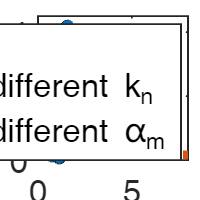

colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];

%Data
Data_Berry2022=readmatrix('../Data/Data_Berry2022.xlsx','sheet','FC','range','B:D');
Data_Sun2013=readmatrix('../Data/Data_Sun2013.xlsx','sheet','speeds');


%mn experiment and prediction (Figure 2a)
fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

p1=plot(Data_Berry2022(:,1),Data_Berry2022(:,3), ...
    'o', ...
    "MarkerSize",8, ...
    "MarkerEdgeColor",'black',...
    "LineWidth",0.2,...
    "MarkerFaceColor",colors(1), ...
    "DisplayName","Exp. data");
hold on

p2=plot(ones(1,100),linspace(0.2,4,100),'--', ...
    "LineWidth",5, ...
    "Color",colors(6),...
    "DisplayName","Pred. with different k_n");
hold on
p3=plot(mn_am_pre/mn_wt,vpro_am_pre/vpro_wt,'--',...
    "LineWidth",5, ...
    "Color",colors(2),...
    "DisplayName","Pred. with different \alpha_m");
hold off
xlim([0,8])
ylim([0,4.5])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p1 p2 p3],"Interpreter","tex","FontSize",20,'FontName','Helvetica')
ylabel('mRNA production rate fold change','interpreter','tex','FontSize',20);
xlabel('Nuclear mRNA concentration fold change','interpreter','tex','FontSize',20);

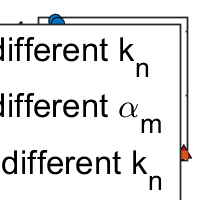




%mn simulation and prediction (Figure 2d)
fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

p1=plot(cmn_kn/cmn_wt,vpro_kn/vpro_wt, ...
    'o', ...
    "MarkerSize",8, ...
    "MarkerEdgeColor",'black',...
    "LineWidth",0.2,...
    "MarkerFaceColor",colors(1), ...
    "DisplayName","Sim. with different k_n");
hold on
p2=plot(cmn_am/cmn_wt,vpro_am/vpro_wt, ...
    '^', ...
    "MarkerSize",8, ...
    "MarkerEdgeColor",'black',...
    "LineWidth",0.2,...
    "MarkerFaceColor",colors(7), ...
    "DisplayName","Sim. with different \alpha_m");
hold on

p3=plot(ones(1,100),linspace(0.2,4,100),'--', ...
    "LineWidth",5, ...
    "Color",colors(6),...
    "DisplayName","Pred. with different k_n");
hold on
p4=plot(mn_am_pre/mn_wt,vpro_am_pre/vpro_wt,'--',...
    "LineWidth",5, ...
    "Color",colors(2),...
    "DisplayName","Pred. with different \alpha_m");
hold off
xlim([0,8])
ylim([0,4.5])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p1 p2 p3 p4],"Interpreter","tex","FontSize",20,'FontName','Helvetica')
ylabel('mRNA production rate fold change','interpreter','tex','FontSize',20);
xlabel('Nuclear mRNA concentration fold change','interpreter','tex','FontSize',20);

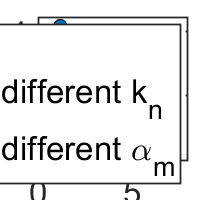




%mc experiment and prediction (Figure 2b)
fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

p1=plot(Data_Berry2022(:,2),Data_Berry2022(:,3), ...
    'o', ...
    "MarkerSize",8, ...
    "MarkerEdgeColor",'black',...
    "LineWidth",0.2,...
    "MarkerFaceColor",colors(1), ...
    "DisplayName","Exp. data");
hold on

p2=plot(ones(1,100),linspace(0.2,4,100),'--', ...
    "LineWidth",5, ...
    "Color",colors(6),...
    "DisplayName","Pred. with different k_n");
hold on
p3=plot(ones(1,100)+0.1,linspace(0.2,4,100),'--',...
    "LineWidth",5, ...
    "Color",colors(2),...
    "DisplayName","Pred. with different \alpha_m");
hold off
xlim([0,8])
ylim([0,4.5])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p1 p2 p3],"Interpreter","tex","FontSize",20,'FontName','Helvetica')
ylabel('mRNA production rate fold change','interpreter','tex','FontSize',20);
xlabel('Cytoplasmic mRNA concentration fold change','interpreter','tex','FontSize',20);

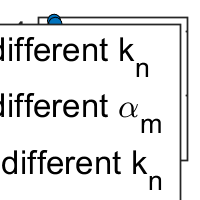




%mc simulation and prediction (Figure 2e)
fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

p1=plot(cmc_kn/cmc_wt,vpro_kn/vpro_wt,...
    'o', ...
    "MarkerSize",8, ...
    "MarkerEdgeColor",'black',...
    "LineWidth",0.2,...
    "MarkerFaceColor",colors(1), ...
    "DisplayName","Sim. with different k_n");
hold on
p2=plot(cmc_am/cmc_wt,vpro_am/vpro_wt, ...
    '^', ...
    "MarkerSize",8, ...
    "MarkerEdgeColor",'black',...
    "LineWidth",0.2,...
    "MarkerFaceColor",colors(7), ...
    "DisplayName","Sim. with different \alpha_m");
hold on

p3=plot(ones(1,100),linspace(0.2,4,100),'--', ...
    "LineWidth",5, ...
    "Color",colors(6),...
    "DisplayName","Pred. with different k_n");
hold on
p4=plot(ones(1,100)+0.1,linspace(0.2,4,100),'--',...
    "LineWidth",5, ...
    "Color",colors(2),...
    "DisplayName","Pred. with different \alpha_m");
hold off
xlim([0,8])
ylim([0,4.5])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p1 p2 p3 p4],"Interpreter","tex","FontSize",20,'FontName','Helvetica')
ylabel('mRNA production rate fold change','interpreter','tex','FontSize',20);
xlabel('Cytoplasmic mRNA concentration fold change','interpreter','tex','FontSize',20);

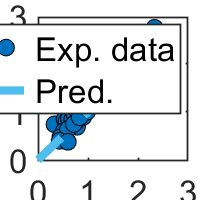




% vdeg vs vpro expermient and prediction (Figure 2c)
fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

p1=plot(Data_Sun2013(:,4),Data_Sun2013(:,5),'o', ...
    "MarkerSize",10, ...
    "MarkerEdgeColor",'black',...
    "MarkerFaceColor",colors(1), ...
    "DisplayName","Exp. data");
hold on

p2=plot([0,2],[0,2],'--', ...
    "LineWidth",5, ...
    "Color",colors(6),...
    "DisplayName","Pred.");
hold off
xlim([0,3])
ylim([0,3])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p1 p2],"Interpreter","tex","FontSize",20)
xlabel('Degradation rate fold change','interpreter','tex','FontSize',20);
ylabel('Production rate fold change','interpreter','tex','FontSize',20);

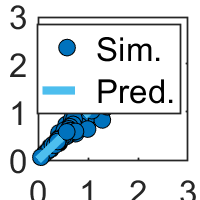





% vdeg vs vpro simulation and prediction (Figure 2f)
fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

p1=plot(vdeg_tot/vdeg_wt,vpro_tot/vpro_wt,'o', ...
    "MarkerSize",10, ...
    "MarkerEdgeColor",'black',...
    "MarkerFaceColor",colors(1), ...
    "DisplayName","Sim.");
hold on
p3=plot([0,2],[0,2],'--', ...
    "LineWidth",5, ...
    "Color",colors(6),...
    "DisplayName","Pred.");
xlim([0,3])
ylim([0,3])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p1 p3],"Interpreter","tex","FontSize",20)
xlabel('Degradation rate fold change','interpreter','tex','FontSize',20);
ylabel('Production rate fold change','interpreter','tex','FontSize',20);